# Course 2. Example 2.2: Quandprog

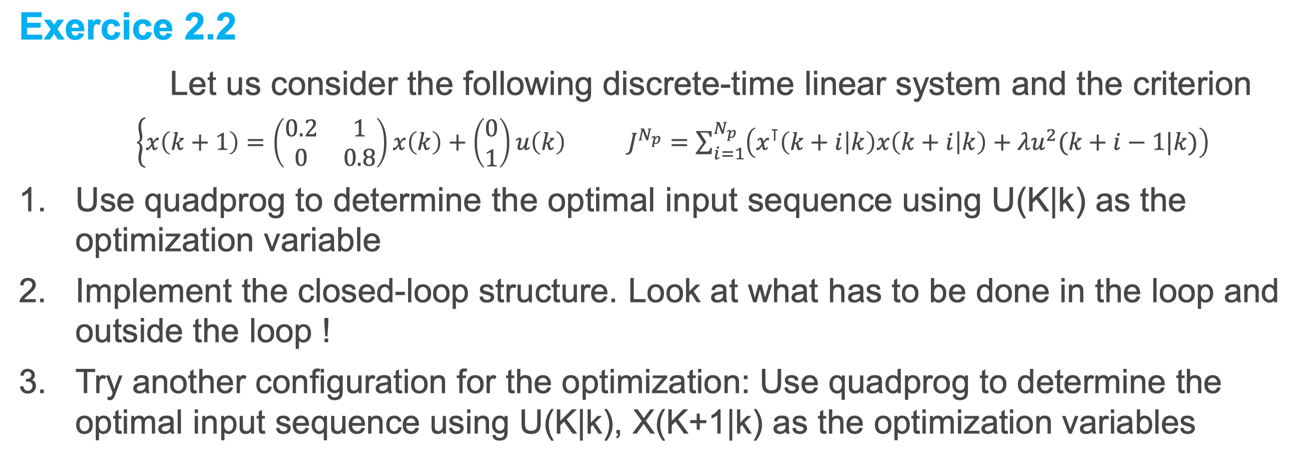

### Initialisation

clear;
close all;
clc

#### **Q1: Model prediction**

% System definition
A=[0.2 1 ;0 0.8];
B=[0;1];
nx=size(A,1);
nu=size(B,2);

% Model prediction
Np=4;
F=zeros(Np*nx,nx);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=A^i ;
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=A^(i-j)*B;
    end
end


#### Q2: Feedback Control

% Objective function
lambda=1;

Q=eye(nx);
R=lambda;

Qx=zeros(nx*Np);
Ru=zeros(nu*Np);

for i =1:Np
    Qx(nx*(i-1)+1:nx*i,nx*(i-1)+1:nx*i)=Q;
    Ru(nu*(i-1)+1:nu*i,nu*(i-1)+1:nu*i)=R;
end

#### Q3: Optimal feedback (off-line computation)

First=zeros(nu,nu*Np);
First(nu,nu)=eye(nu);
K_Np=First*(H'*Qx*H+Ru)^(-1)*H'*Qx*F;

#### Q3: Closed-loop implementation

Use quadprog to determine the optimal input sequence using U(K|k) as the optimization variable.

Nsimu=50;
xinit=[1;1];
xk=xinit;
H_quad = 2*(H'*Qx*H + Ru); % indenpendent from k
X1 = [];
for i=1:Nsimu
    X1 = [X1 xk];
    f_quad = 2*H'*Qx*F*xk;
    [Uopt,Jopt] = quadprog(H_quad,f_quad);
    uk=First*Uopt; %optimal control
    xkp1=A*xk+B*uk;
    xk=xkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


X1

X1 =     1.0000    1.2000    0.3911    0.0884    0.0147    0.0014   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    1.0000    0.1511    0.0102   -0.0030   -0.0016   -0.0004   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

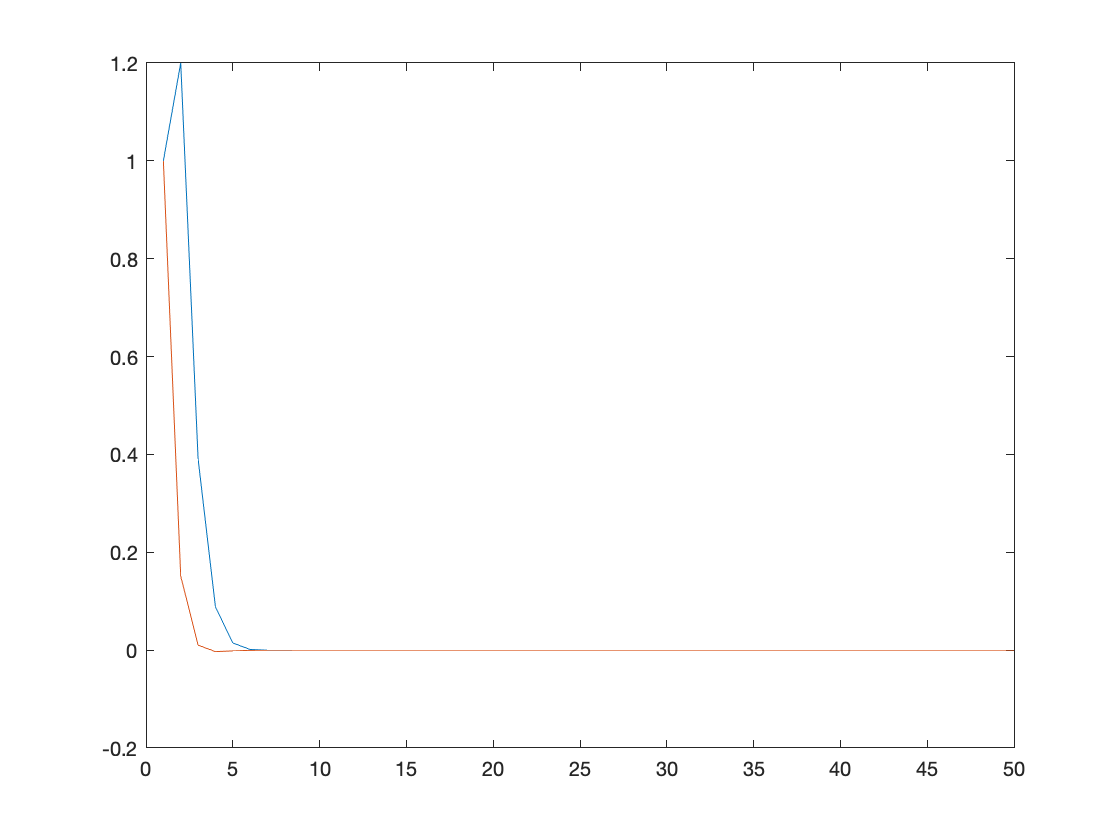

plot(1:Nsimu,X1);

#### Q4： Try another configuration for the optimization: 

Use quadprog to determine the optimal input sequence using U(K|k), X(K+1|k) as the optimization variables.

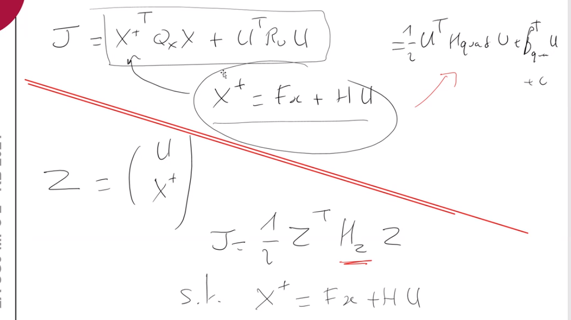

Hz = zeros((nx+nu)*Np);
Hz = blkdiag(Ru,Qx);
Aeq = [-H eye(Np*nx)]; % Aeq*Z = beq
FirstZ = [First zeros(1,Np*nx)]; % Z = [U(K|k), X(K+1|k)]

Nsimu=50;
xinit=[1;1];
xk=xinit;
X2 = [];
for i=1:Nsimu
    X2 = [X2 xk];
    beq = F*xk;
    [Zopt,JNP] = quadprog(Hz,[],[],[],Aeq,beq);
    uk=FirstZ*Zopt; %optimal control U
    xkp1=A*xk+B*uk;
    xk=xkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


X2

X2 =     1.0000    1.2000    0.3911    0.0884    0.0147    0.0014   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    1.0000    0.1511    0.0102   -0.0030   -0.0016   -0.0004   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

plot(1:Nsimu,X2);

#### Q5: Analysis of the closed-loop system

eigenvalues=eig(A-B*K_Np);
norm(eigenvalues(1),1)

ans = 0.2112